#### HTMR project

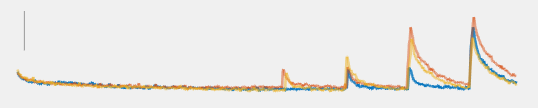

nNeuron = input('the neuron to plot  \n ');

traceTemp = reshape(normDeltaF(:,nNeuron), [size(normDeltaF,1)/3, 3]);
trace = traceTemp;

% trace = zeros(680,3);
% for i = 1:3
%     % [~,trace(:,i),~] = RobustDetrend(traceTemp(:,i),6,0.975);
%     trace(:,i) = detrend(traceTemp(:,i), 6);
% end

f = figure('units','inch',"Position", [1, 1, 5.6, 1.12]);
set(gcf,'Visible','on')
set(gca, 'OuterPosition', [0,0,1,1])
ax = gca;
outerpos = ax.OuterPosition;
ti = ax.TightInset;
left = outerpos(1) + ti(1);
bottom = outerpos(2) + ti(2);
ax_width = outerpos(3) - ti(1) - ti(3);
ax_height = outerpos(4) - ti(2) - ti(4);
ax.Position = [left bottom ax_width ax_height];
p1 = plot(trace(:,1),'LineWidth',2);
hold on
p2 = plot(trace(:,2),'LineWidth',2);
p3 = plot(trace(:,3),'LineWidth',2);
p1.Color(4) = 0.8;
p2.Color(4) = 0.5;
p3.Color(4) = 0.5;
yl = ylim;
if yl(2)< 0.2
    ylim([yl(1), 0.6])
end
xl = xlim;
yl = ylim;
box off
axis off
line([10, 10], [yl(2)*0.95, yl(2)*0.95-0.2],'LineWidth',0.5,'Color',[0.6, 0.6, 0.6]) 


a = strsplit(path,filesep);
% folder = 'C:\Users\Qi_Li\Dropbox (HMS)\RIG_DATA\Second Paper\LQ_figure\indentation_500ms\new_022623\';
folder = 'E:\Dropbox (HMS)\RIG_DATA\Second Paper\LQ_figure\adaptation\030423\';
% folder = uigetdir();
% exportgraphics(f,[folder,a{end-1},'_neuron_', num2str(nNeuron), '.png'],'Resolution',600);
if ~exist('pathList', "var")
    pathList = a{end-1};
else
    pathList = [pathList; a{end-1}];
end

#### For Genital project

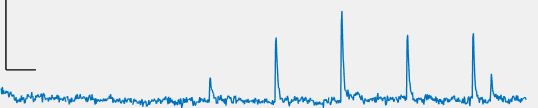

nNeuron = input('the neuron to plot  \n ');

traceTemp = reshape(normDeltaF(:,nNeuron), [880, 3]);
nforce = 8;
trace = mean(traceTemp, 2);
trace(1:size(traceTemp, 1)/nforce:end) = NaN;

% trace = zeros(680,3);
% for i = 1:3
%     [~,trace(:,i),~] = RobustDetrend(trace(:,i),6,0.975);
% end

f = figure('units','inch',"Position", [1, 1, 5.6, 1.12]);
set(f,'Visible','on')
ax = gca;
% ax.OuterPosition =  [0,0,1,1];
% outerpos = ax.OuterPosition;
% ti = ax.TightInset;
% left = outerpos(1) + ti(1)*2;
% bottom = outerpos(2) + ti(2);
% ax_width = outerpos(3) - ti(1)*2;
% ax_height = outerpos(4) - ti(2) - ti(4);
% ax.Position = [left, bottom, ax_width,ax_height];
ax.Position = [0, 0, 1, 1];
plot(trace,'LineWidth', 1)
yl = ylim;
if yl(2)< 0.1
    ylim([yl(1), 0.6])
end
yl = ylim;
box off
axis off
% line([10, 10], [yl(2)*0.95, yl(2)*0.95-0.2],'LineWidth',1,'Color',
% 'black') % for HTMR project, the scale bar is 0.2
yscale = 0.1;
line([10, 10], [yl(2)*0.95, yl(2)*0.95-yscale],'LineWidth',1,'Color', 'black'); % y scale bar is 0.1
line([10, 60], [yl(2)*0.95-yscale, yl(2)*0.95-yscale],'LineWidth',1,'Color', 'black'); %x scale bar is 5 second
a = strsplit(path,filesep);
% folder = 'C:\Users\Qi_Li\Dropbox (HMS)\RIG_DATA\Second Paper\LQ_figure\indentation_500ms\new_091222\';
folder = 'Z:\GintyLab\Qi\Analysis Spreadsheets\Genital\calcium_MEA\';
exportgraphics(f,fullfile(folder,[a{end-1},'_neuron_', num2str(nNeuron), '.eps']),'Resolution',600);

Plot the indentation stimuli

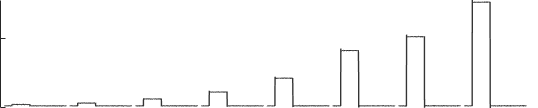

f1 = figure('units','inch',"Position", [1, 1, 5.6, 1.12]);
set(f1,'Visible','on')
forcePlot = mean(forceSplit, 2);
forcePlot = forcePlot*50;
for i= 1:15000
forcePlot(i:size(forceSplit,1)/nforce:end)  = NaN;
end

ax = gca;
ax.OuterPosition =  [0,0,1,1];
% outerpos = ax.OuterPosition;
% 
% ti = ax.TightInset;
% left = outerpos(1) + ti(1)*2;
% bottom = outerpos(2) + ti(2);
% ax_width = outerpos(3) - ti(1)*2;
% ax_height = outerpos(4) - ti(2) - ti(4);
% ax.Position = [left, bottom, ax_width,ax_height];
ax.Position = ax.OuterPosition;
plot(forcePlot,'LineWidth', 1,'color', [0.2, 0.2, 0.2])
yticks([0, 50])
box off
ax.XAxis.Visible = 'off';
ax.FontSize = 12; 
% yl = ylim;
% line([10, 10], [yl(2)*0.95, yl(2)*0.95-0.2],'LineWidth',1,'Color', 'black')
folder = 'Z:\GintyLab\Qi\Analysis Spreadsheets\Genital\calcium_MEA\';
exportgraphics(f1,[folder,'indent','.pdf']);